%{
ES115- Class-Project Module 1 project bank
Author: Matthew Chietro
Version: 1.0
Date: 2026-04-13
Purpose:
    - To model and analyze the speed profile of an autonomous cart using a
      quadratic function of time.
    - To compute and visualize both speed and numerically estimated acceleration.
    - To determine when maximum speed occurs and estimate acceleration near that point.

Input:
    - Time vector from 0 to 20 seconds (t = 0:0.2:20)

Output:
    - Plot of speed vs time
    - Plot of acceleration vs time (numerical derivative)
    - Maximum speed value and corresponding time
    - Estimated acceleration near maximum speed printed to command window

Engineering Algorithms:
    - Define time vector using fixed step size (0.2 s)
    - Evaluate quadratic speed function v(t)
    - Plot speed vs time and mark midpoint (t = 10 s)
    - Compute time step dt
    - Use finite difference (diff) to approximate acceleration a(t) ≈ Δv/Δt
    - Align acceleration values to midpoint times
    - Plot acceleration vs time in separate figure
    - Find maximum speed using max()
    - Identify time index of maximum speed
    - Estimate acceleration near maximum speed using neighboring data point
    - Print results using fprintf

MATLAB tools/functions:
    - vector operations
    - plot, xlabel, ylabel, title, grid, xline
    - diff, max
    - fprintf
    - indexing and array slicing
    - figure
%}

Autonomous Cart Speed Profile (Quadratic + Numerical Change)

A small autonomous cart follows a speed profile over time modeled by:

v(t) = −0.2(t − 10)2 + 20

for 0 ≤ t ≤ 20 seconds.

Tasks

1. Implement v(t) and evaluate it on t = 0 : 0.2 : 20.

t = 0:0.2:20;           % time vector (seconds)
v = -0.2*(t - 10).^2 + 20;  % speed profile (m/s)

2. Plot speed vs time.

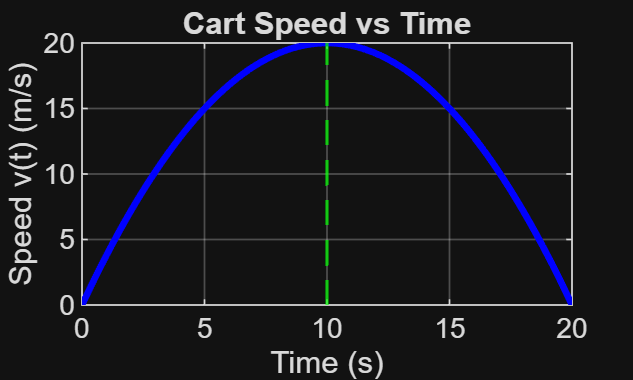

figure(1);
plot(t, v, 'b-', 'LineWidth', 2);%plotting the speed vs time graph
xlabel('Time (s)');%labeling x axis
ylabel('Speed v(t) (m/s)');%labeling y axis
title('Cart Speed vs Time');%giving the graph a title
xline(10,'g--','LineWidth',1);%giving an x line for visual comparison with the next graph
grid on;

3. Use numerical differences to estimate the acceleration a(t) ≈ ∆v

∆t .

dt = t(2) - t(1);       % this defines the change in time
a = diff(v) / dt;       % numerical derivative (acceleration)
t_a = t(1:end-1) + dt/2; % associate acceleration at midpoints

4. Plot acceleration vs time on a separate figure.

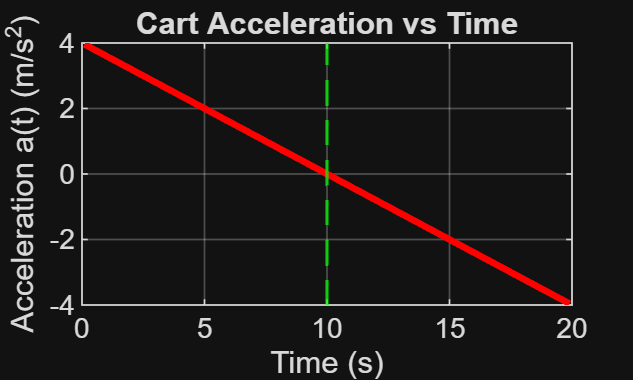

figure(2);
plot(t_a, a, 'r-', 'LineWidth', 2);%plotting accel vs time
xlabel('Time (s)');%labeling the x axis
ylabel('Acceleration a(t) (m/s^2)');% labeling the y axis
title('Cart Acceleration vs Time');%giving the graph a title
xline(10,'g--','LineWidth',1);%giving an x line for visual comparison
grid on;

5. Identify the time when speed is maximized and interpret what acceleration is near that time

% Find maximum value and its index in velocity vector
[v_max, idx_max] = max(v);
t_max = t(idx_max);  % time of maximum speed
% Use previous index as a simple approximation of acceleration at peak
a_at_max = a(idx_max-1);  % approximate acceleration near max speed
fprintf('Maximum speed = %.2f m/s occurs at t = %.2f s\n', v_max, t_max);
fprintf('Acceleration near max speed ≈ %.2f m/s^2\n', a_at_max);

Maximum speed = 20.00 m/s occurs at t = 10.00 s


Acceleration near max speed ≈ 0.04 m/s^2


%Creating data pairs
CreateDataPairs (v, a_aligned);

va =          0    0.7920    1.5680    2.3280    3.0720    3.8000    4.5120    5.2080    5.8880    6.5520    7.2000    7.8320    8.4480    9.0480    9.6320   10.2000   10.7520   11.2880   11.8080   12.3120   12.8000   13.2720   13.7280   14.1680   14.5920   15.0000   15.3920   15.7680   16.1280   16.4720   16.8000   17.1120   17.4080   17.6880   17.9520   18.2000   18.4320   18.6480   18.8480   19.0320   19.2000   19.3520   19.4880   19.6080   19.7120   19.8000   19.8720   19.9280   19.9680   19.9920
    3.9600    3.9200    3.8400    3.7600    3.6800    3.6000    3.5200    3.4400    3.3600    3.2800    3.2000    3.1200    3.0400    2.9600    2.8800    2.8000    2.7200    2.6400    2.5600    2.4800    2.4000    2.3200    2.2400    2.1600    2.0800    2.0000    1.9200    1.8400    1.7600    1.6800    1.6000    1.5200    1.4400    1.3600    1.2800    1.2000    1.1200    1.0400    0.9600    0.8800    0.8000    0.7200    0.6400    0.5600    0.4800    0.4000    0.3200    0.2400    0.1600    


%This function does not return a value
function  CreateDataPairs (v, a_aligned)  % Function requires two input arguments 
  va =[v; a_aligned] % Stak the first matrix on seond
  fid = fopen('DataPairsVA.txt', 'wt'); %opens a text file to put data
  fprintf (fid, '%4.0f %4.0f \n', va); %prints the data in the file
  fclose(fid);  %closes file
  T = table ([v; a_aligned]);% creates a table to make a 2x101 array
  filename = ('DataPairsVA.dat');%identifies a file name for the data pairs
  writetable(T, filename);%writes the table into the file
end